# INPUT

[audio_data, Fs] = audioread("FichiersSon\2notes.wav");

## Audio player

sound(audio_data, Fs, 8);

Unrecognized function or variable 'audio_data'.


Fs = 62973
dt = 1/Fs;
time =linspace(0,length(audio_data)*dt,length(audio_data));
len_time = length(time);


## Plot for amplitude vs Time

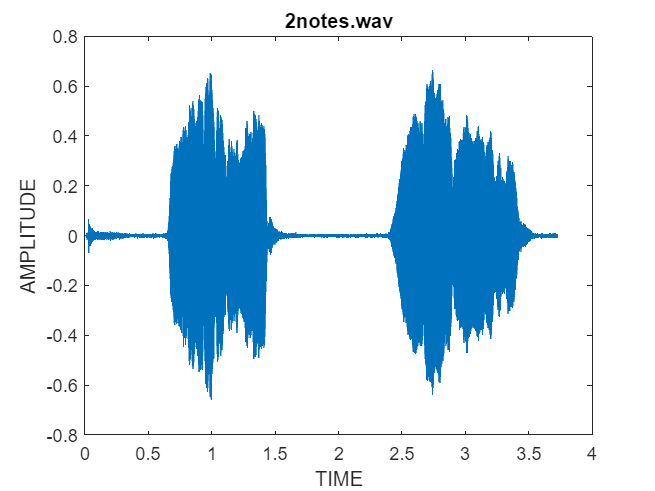


plot(time,audio_data);
xlabel("TIME");
ylabel("AMPLITUDE");
title("2notes.wav");

## Power and Normarlized_Power

Power = pow(len_time,audio_data);
disp(Power);

   6.0511e+03



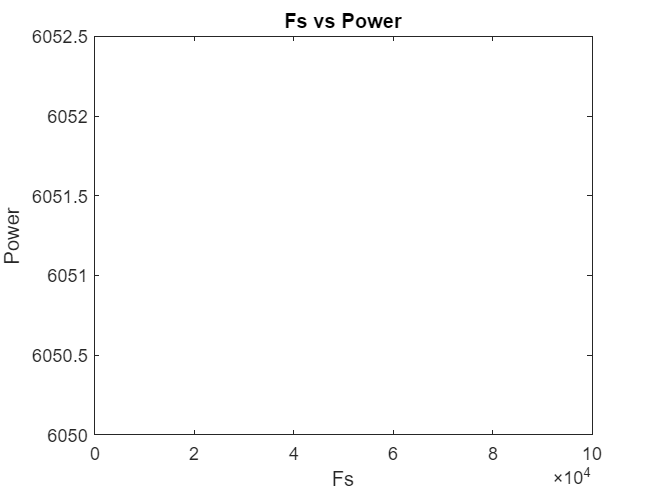

Normalized_Power = pow(len_time,audio_data)/len_time;

display(Normalized_Power);

function [pow] = pow(len_time,amp)
    pow=0;
    for i = 1:len_time
        pow = pow + amp(i)^2;
    end

end
